clear
data=readtable("dataClean.csv")

data = 8760×12 table
           tstamp             AC      tou_id     DC     weekDay    Sat    Sun    wrkHr    dayTime    Off_Peak    Peak    Standard
    ____________________    ______    ______    ____    _______    ___    ___    _____    _______    ________    ____    ________

    01-Jan-2022 00:00:00    96.855      1       52.2       0        1      0       0         0          1         0         0    
    01-Jan-2022 01:00:00    97.053      1         52       0        1      0       0         0          1         0         0    
    01-Jan-2022 02:00:00    97.229      1       52


numObservations = size(data);
percentSplit = 0.7;

idxTrain = 1:floor(percentSplit*numObservations);
X = data(idxTrain,:);

SARIMA_AC = arima('Constant',NaN,'D',0,'MALags',1:2,'Seasonality',24,'SARLags',24,'SMALags',24,'Distribution','Gaussian');
SARIMA_AC = estimate(SARIMA_AC,X.AC,'Display','off')

SARIMA_AC =   arima with properties:

     Description: "ARIMA(0,0,2) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 48
               D: 0
               Q: 26
        Constant: 0.119306
              AR: {}
             SAR: {0.198245} at lag [24]
              MA: {0.986015 0.565565} at lags [1 2]
             SMA: {-0.947044} at lag [24]
     Seasonality: 24
            Beta: [1×0]
        Variance: 265.561


SARIMA_DC = arima('Constant',NaN,'D',0,'MALags',1:2,'Seasonality',24,'SARLags',24,'SMALags',24,'Distribution','Gaussian');
SARIMA_DC = estimate(SARIMA_DC,X.DC,'Display','off')

SARIMA_DC =   arima with properties:

     Description: "ARIMA(0,0,2) Model Seasonally Integrated with Seasonal AR(24) and MA(24) (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 48
               D: 0
               Q: 26
        Constant: 0.0824782
              AR: {}
             SAR: {0.337775} at lag [24]
              MA: {1.29286 0.650057} at lags [1 2]
             SMA: {-0.947055} at lag [24]
     Seasonality: 24
            Beta: [1×0]
        Variance: 178.105

nForecast = 24

nForecast = 24

load = zeros(length(data.AC),1)

load =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


load_preds = zeros(length(data.AC), nForecast);
for j = 76:(length(data.AC(:))-24)
    offset = j;
    [Y_ac, ] = forecast(SARIMA_AC, nForecast, data.AC(1:offset-1) );
    [Y_dc, ] = forecast(SARIMA_DC, nForecast, data.DC(1:offset-1) );
    load(j) = data.AC(offset-1) + data.DC(offset-1);
    load_preds(j,:) = Y_ac + Y_dc;
end




load_actual_test = data.AC + data.DC;

if load_actual_test(75) == load(76) 
    display("you were right muthafucka")
else
    display(load_actual_test(75:77))
    display(load(75:77))
end

  157.1050
  156.5500
  155.7600



         0
  157.1050
  156.5500



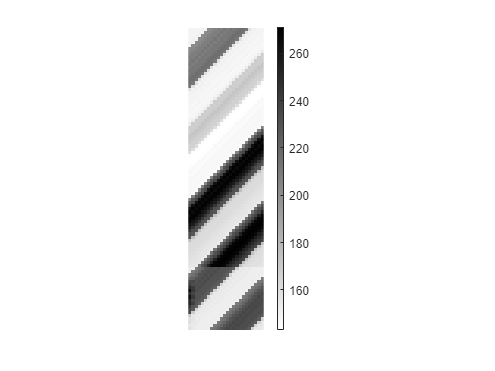



for i = 1:75 
    load_preds(i,:) = load_actual_test(i:i+23)';
end

% Display the array as an image
imagesc(load_preds(1:96,:));

% Use inverted gray colormap (so higher values are darker)
colormap(flipud(gray));

% Adjust the appearance
axis equal tight off;  % Makes pixels square, removes axis, and fits the display
colorbar;  % Shows a colorbar for reference



csvwrite("load_preds.csv",load_preds)